# Chap 2 : Linear regreession with least square estimate

A. Rey, HES-SO MSE, 02.2022

clear;

## Exercice 2.2 Signal approximation and de-noising

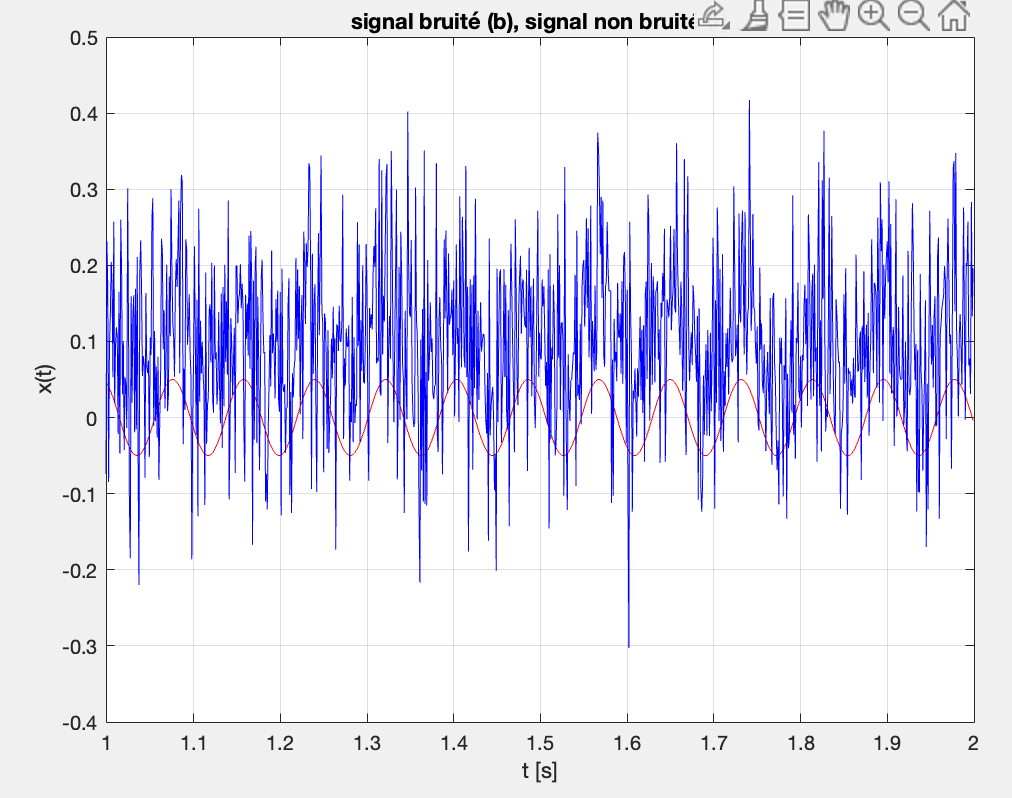

Figure 1: Noisy signal (blue), original and un-noisy signaal (red)

In this exemple of noisy signal see in Figure 1, we need to recover the original signal. The original signal has a frequency between 10 and 15 Hz with an unknown amplitude and phase. The whole signal is a record of 10'000 samples with a sampling frequency of 1 kHz.

In order to use the least square approximation we write a $n$ overdetermined equation system that for each sample of the signal $x[n]$ correspond a sum of pondered basis signals $\phi_1 = [1,1,1,1, ...]$ and $\phi_{i} = sin(2 \pi f_i t)$ and $\phi_{j} = cos(2 \pi f_j t)$:

$x[n] = k_1 \phi_1[n] + k_2  \phi_2[n] + \cdots + k_m  \phi_m[n] $     (1)

This is a linear system of equations with the unknown $k_1 \ldots k_m$ bit it is overdetermined because the number of equation is much greather than the number on unknown.

in matrix form we could write it as :

$\Phi[n] \cdot \Theta = x^T[n] $     (2)

where 

$ \Phi = [  \phi^T_1[n],  \phi^T_2[n] , \cdots , \phi^T_m[n]  ]$     (3)

So we could find the solution by solving by pseudo inverse. 

### Import the data and plot

First import the data in the file `NoisySignal.mat` and plot it.

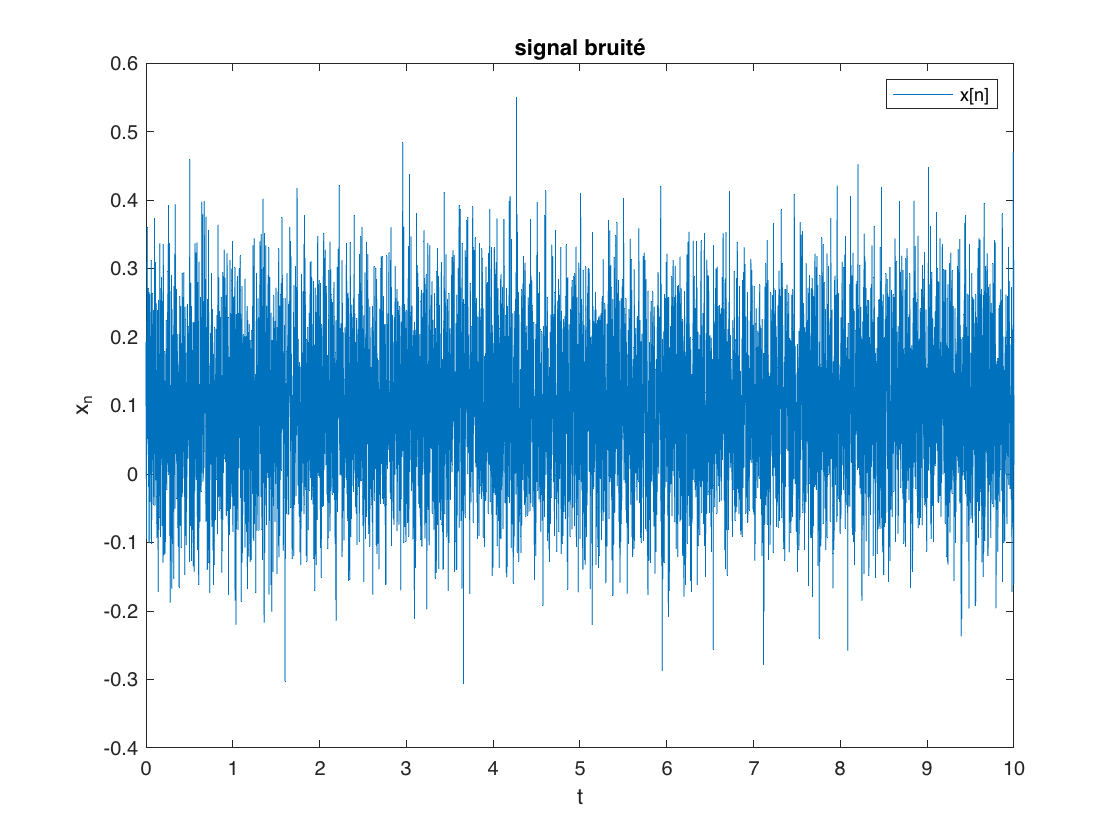

load('ex22_RegressionLinSignal_data.mat'); %load N, t, x, xn

figure
    plot(t, xn);
    legend('x[n]')
    xlabel('t')
    ylabel('x_n')
    title('signal bruité')

### Regressors vectors build

First we need to build the regression vectors $\Phi_i [n]$ containing each one a base function with $N$ samples as the length of the signal $x$.

as regressor vertors we need to generate à constant =1 vector because we could se the x signal has an ofset, and sin vectors having an amplitude of 1 and a frequency f between 10 and 15 Hz with a step of 0.1 Hz ( because the resolution of frequency we could resolve could be > 1/Duration, as the signal as a 10s duration, the frequency resolution that we can have is 1/10s=0.1Hz). The same of the regressors with cos function at the same frequency:

First build a vector containing all the freq values from 10 to 15 Hz with a step of 0.1 Hz let's call it f.

Second generate the regressors : $\phi_1 = [1,1,1,1, ...]$ and $\phi_{i} = sin(2 \pi f_i t)$ and $\phi_{j} = cos(2 \pi f_j t)$

and third generate the regressors matrix $\Phi$ containing all the $M$ ragressors as column vectors :


$$\Phi = \left[\matrix{1 & \sin(2\pi f_1t_1) & \cos(2\pi f_0t_1) & \sin(2\pi f_1t_1) & \cos(2\pi f_1t_1) & \cdots &  \sin(2\pi f_nt_1) & \cos(2\pi f_nt_1) \cr 1 & \sin(2\pi f_1t_2) & \cos(2\pi f_1t_1) &  \cos(2\pi f_0t_2) & \sin(2\pi f_1t_2) & \cdots &  \sin(2\pi f_nt_2) & \cos(2\pi f_nt_2) \cr \vdots & \vdots & \vdots & \vdots & \vdots & \ddots & \vdots & \vdots \cr 1 & sin(2\pi f_1t_N) & \cos(2\pi f_0t_N) & \cos(2\pi f_1t_N) & \sin(2\pi f_1t_N) & \cdots & \sin(2\pi f_0t_N) & \cos(2\pi f_0t_N)} \right]$$


f = 10:0.1:15; %10 to 15Hz by step of 0.1Hz
M = 2*length(f)+1;    % 103 = 2x51+1

% Phi matrix construction :
phi_1 = ones(N, 1);
phi_1 = phi_1 / norm(phi_1); % normalization

phi_i = sin(2*pi.*f'.*t)';
phi_i = phi_i / norm(phi_i); % normalization

phi_j = cos(2*pi.*f'.*t)';
phi_j = phi_j / norm(phi_j); % normalization

% dot product must give 0 as the two regressors are orthonormal
% phi_i(1,:) * phi_j(1,:)'

Phi = zeros(N, M);
Phi(:,1) = phi_1;
Phi(:,2:2:end) = phi_i;
Phi(:,3:2:end) = phi_j;

% method above follow the theory,
% to get same result as the correction of the teacher
% the following Phi matrix must be used
% the final results are the same, it's just Phi which
% is organized differently
%Phi = [phi_1, phi_j, phi_i];

### Projection of the signal x into the new vectorspace composed by regressors

Solving the overdetermined equation system equation (2) with pseudo inverse matrix 

$P =(\Phi[n] ^T \Phi[n])^{-1}\Phi[n]^T    $      $\Theta = P \cdot x^T[n]$     (4)

In our case the regressors are orthonormal and the product $(\Phi[n] ^T \Phi[n]) = I$ is an identity matrix with size $M \times M$.

The consequence of this fact is the simplicity of the coefficients computation that are given by : 

$\Theta =(\Phi[n] ^T \Phi[n])^{-1}\Phi[n]^T   x[n]^T =  \Phi[n]^T   x[n]^T$     (5)

Compute the coefficients $\Theta $ using the pseudoinverse P as in (4), and the simple projection givent in (5). Plot the coefficients.

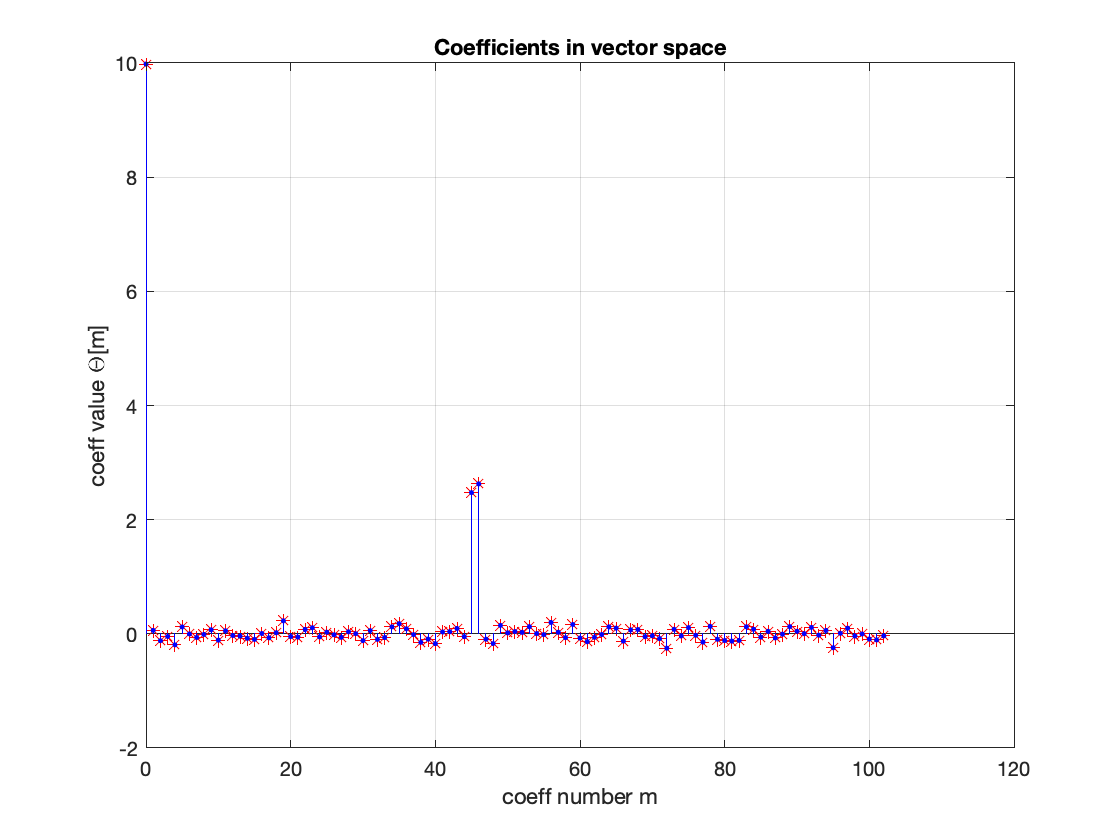

% to check
%I = Phi'*Phi;
%P = inv(I)*Phi';
%Theta = P*xn';

% by pseudo-inverse:
%Theta = inv(Phi'*Phi)*Phi'*xn';
Theta = (Phi'*Phi)\Phi' * xn';

% by projection
Theta_proj = Phi'*xn';

% Coefficients
figure
    stem(0:M-1, Theta, 'r*'); hold on;
    stem(0:M-1, Theta_proj, 'b.');
    title('Coefficients in vector space')
    xlabel('coeff number m')
    ylabel('coeff value \Theta[m]')
    grid;

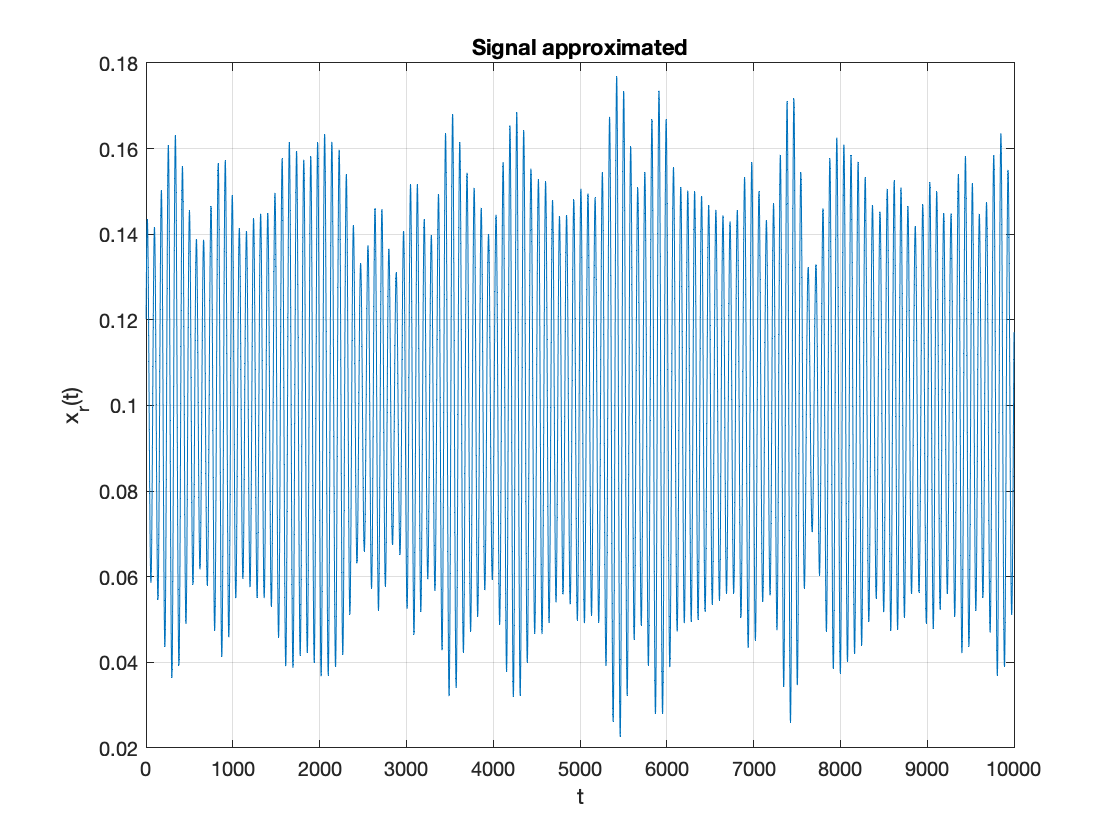

% Signal approximated
xr = Phi*Theta;
figure;
plot(xr)
title('Signal approximated');
xlabel('t')
ylabel('x_r(t)')
grid;

Error between the approximated and the original signal computed as $W_e = \frac{||e||^2}{N^2}$ with $e=x_r[n]-\hat{x}[n]$

xe = xn-xr';
We = norm(xe)^2/N^2

We = 9.8758e-07

Wxr = norm(xr)^2/N^2

Wxr = 1.1359e-06

Wxn = norm(xn)^2/N^2

Wxn = 2.1235e-06

### Signal denoising

If the goal is to retrive a specific signal that we know some details as the shape (sinus, ...) we just take the specific coefficients (those with the bigger magnitude), and only with this coefficients we compute the retrived signal. In this case we take only 2 coefficients corresponding the sinus and cosinus regressors at the same frequency.

The frequency $f_{max}$ of the signal corresponds to the maximum coefficient value index (`icos`):

[MaxCos, icos] = max(Theta(3:2:end)) % éléments impairs (cos)

MaxCos = 2.6281

icos = 23

[MaxSin, isin] = max(Theta(2:2:end)) % éléments pairs (sin)

MaxSin = 2.4742

isin = 23

fmax = f(isin) %Hz

fmax = 12.2000

%fmax = f(icos)

The signal recovery is then computed with 2 coefficients MaxCos and MaxSin, the amplitude Axr RMS could be computed and also the phase Phxr.

Axr = sqrt( (MaxCos/sqrt(N/2))^2 + (MaxSin/sqrt(N/2))^2 ) % Vpk

Axr = 0.0510

Phxr = atan2(MaxSin, MaxCos)

Phxr = 0.7552

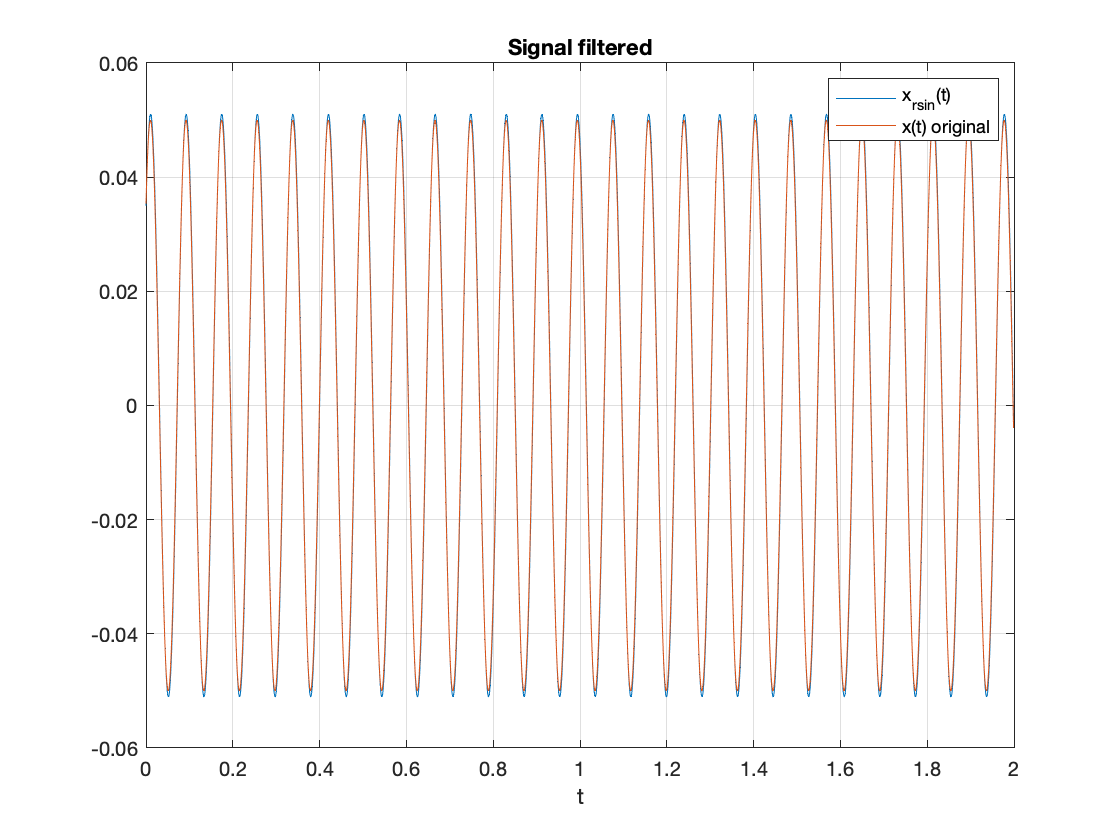

xrsin = Axr*sin(2*pi*fmax*t+Phxr);

range = [1:2E3];

figure
    plot(t(range), xrsin(range), ...
         t(range), x(range))
    title('Signal filtered');
    xlabel('t')
    legend('x_{rsin}(t)','x(t) original')
    grid;

% Error
xre = x-xrsin;
Wre = norm(xre)^2/N^2

Wre = 1.7086e-10